# Machine Learning Classifier to Predict Alzheimer's Disease from Microarray Data

Authors: Kristen Norray, Zeal Jinwala, Henry Hollis

if files dont exist:

    %run r script from here"rscript"

-designed project to work on macOS (rsciprt should auto work for us)

%read in z-normed data, preprocessed in R
opts = detectImportOptions('../NormedData/GSE63060_z_intersectGenes.csv');
opts.DataLines = 3;
opts.VariableNamesLine = 2;
GSE63060 = readtable('../NormedData/GSE63060_z_intersectGenes.csv', opts);

opts = detectImportOptions('../NormedData/GSE63061_z_intersectGenes.csv');
opts.DataLines = 3;
opts.VariableNamesLine = 2;
GSE63061 = readtable('../NormedData/GSE63061_z_intersectGenes.csv', opts);

GSE63061_meta = readtable('../NormedData/GSE63061_subject_data.csv');

GSE63060_meta = readtable('../NormedData/GSE63060_subject_data.csv');

Train_data = [GSE63061; GSE63060];
Train_labels = [GSE63061_meta; GSE63060_meta];
Train_labels = Train_labels{:, 'characteristics_ch1'};

unique(Train_labels)

ans = 7×1 cell array
    {'status: AD'            }
    {'status: CTL'           }
    {'status: CTL to AD'     }
    {'status: MCI'           }
    {'status: MCI to CTL'    }
    {'status: OTHER'         }
    {'status: borderline MCI'}


We remove the "OTHER, " "borderline MCI," "MCI to CTL, " and "CTL to AD" cases (only ~4 subjects).  We convert MCI to AD to maintain a binary classification problem.

rm =strcmp(Train_labels, 'status: MCI to CTL') |...
    strcmp(Train_labels, 'status: CTL to AD') |...
    strcmp(Train_labels, 'status: borderline MCI') |...
    strcmp(Train_labels, 'status: OTHER');

Train_labels =  Train_labels(~rm);
Train_data = Train_data(~rm, :);
Train_data_double = table2array(Train_data(:,2:end));
Train_labels = regexprep(Train_labels,'status: ','');
Train_labels_reduced_class = regexprep(Train_labels,'MCI','AD');

bin_labels = zeros(numel(Train_labels_reduced_class), 1);
bin_labels(strcmp(Train_labels_reduced_class, 'AD')) = 1;

cv=cvpartition(Train_labels,'k',10);   %call 10-fold cross val
%filter_selected =sequentialfs(@trainandtest,Train_data_double,...
%     bin_labels,'cv',cv,'options',...
%     statset('display','iter'),'direction','forward');
filter_selected = [582 1130 3102 9375 9891 11710 11917 12230];
%filter_selected = [9692 3467 1336 2637 7481 12587 2521 9613 6 1056 1209 7402 2888 550 6169 4245 45];

### Performance of selected features:

error = crossval(@trainandtest,Train_data_double(:, filter_selected),...
    bin_labels, 'partition',cv);

fprintf('10-fold cross val acc: %.3f',1 - sum(error)/numel(bin_labels))

10-fold cross val acc: 0.665

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4121 |       15.66 |      0.4121 |      0.4121 |       759.68 |    0.0075117 |
|    2 | Best   |     0.33474 |    0.061751 |     0.33474 |     0.34002 |       29.237 |       54.365 |
|    3 | Accept |     0.33474 |    0.044679 |     0.33474 |     0.33474 |    0.0021816 |       335.68 |
|    4 | Best   |     0.25316 |    0.058573 |     0.25316 |     0.26039 |     0.001397 |     0.036234 |
|    5 | Accept |     0.25316 |    0.059049 |     0.25316 |     0.25316 |    0.0013123 |     0.037644 |
|    6 | Best   |     0.25176 |      0.2425 |     0.25176 |     

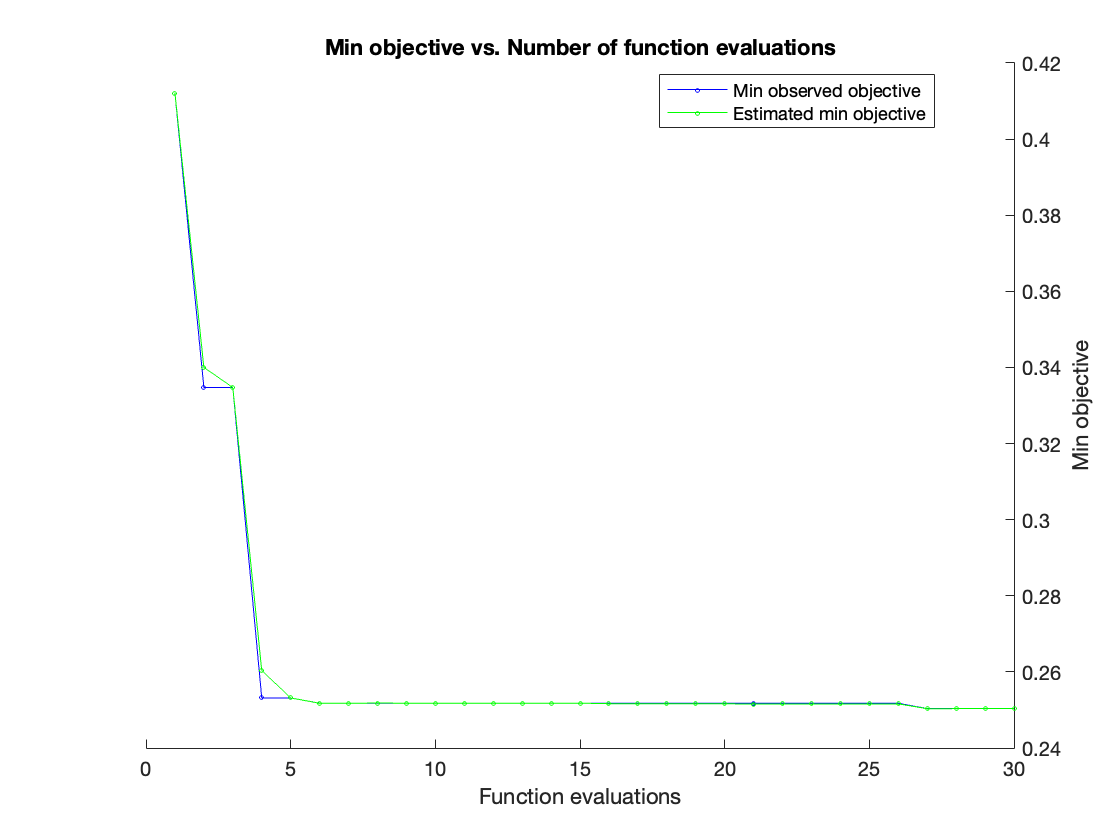

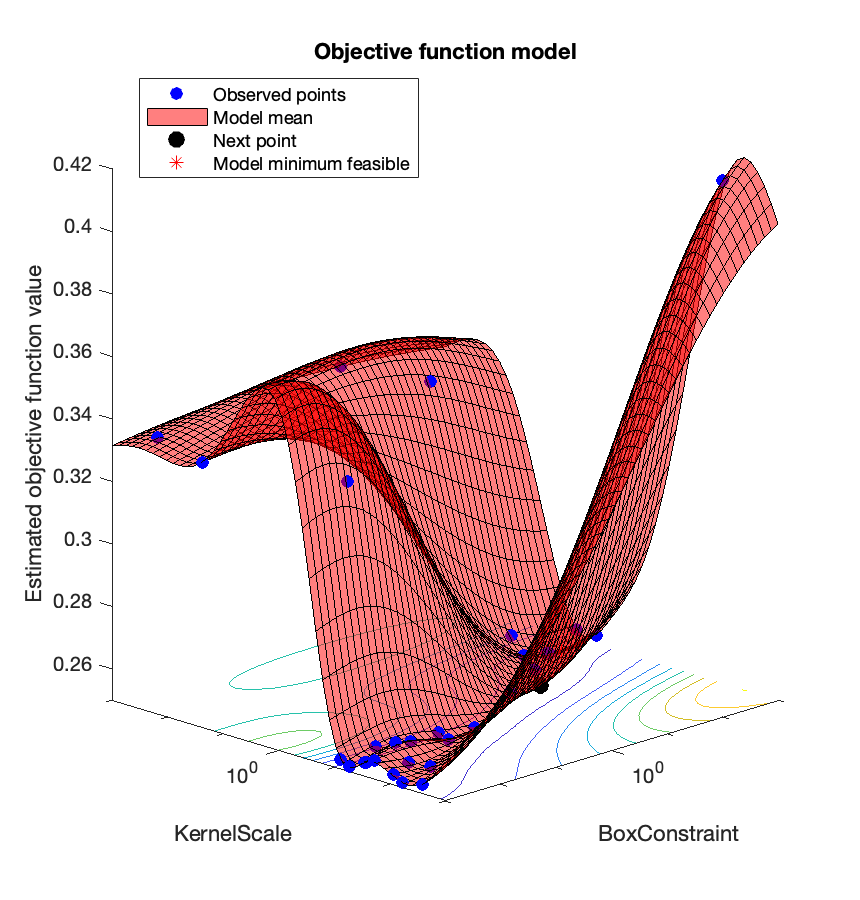


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 37.0568 seconds
Total objective function evaluation time: 24.3736

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       192.88          2.8271   

Observed objective function value = 0.25035
Estimated objective function value = 0.25039
Function evaluation time = 0.24693

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       192.88          2.8271   

Estimated objective function value = 0.25039
Estimated function evaluation time = 0.25477



%model = fitcsvm(Train_data_double(:, filter_selected),bin_labels,'KernelFunction', 'rbf', 'Standardize', true);
model = fitcsvm(Train_data_double(:, filter_selected),bin_labels,'OptimizeHyperparameters','auto', 'Standardize', true);

Remove train data from workspace to speed up livescript:

%clear Train_data; clear Train_data_double; clear GSE63060; clear GSE3061;

opts = detectImportOptions('../NormedData/GSE44772_z_intersectGenes.csv');
opts.DataLines = 3;
opts.VariableNamesLine = 2;
GSE44772 = readtable('../NormedData/GSE44772_z_intersectGenes', opts);
Test_data_double = table2array(GSE44772(:,2:end));

GSE44772_meta = readtable('../NormedData/GSE44772_subject_data.csv');

test_labels = GSE44772_meta(:,4);
test_labels = regexprep(table2cell(test_labels(:, 1)),'disease: ','');
bin_test_labels= zeros(size(GSE44772_meta, 1), 1);
bin_test_labels(strcmp(test_labels, 'A')) = 1;


Accuracy on test set:

preds = predict(model, Test_data_double(:, filter_selected));
accuracy = sum(preds == bin_test_labels)/numel(bin_test_labels)

accuracy = 0.5188

%% How can we improve the accuracy 